## **PART 1**

a = 5; 
whos a;

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              




b = uint8(a);
whos b;

  Name      Size            Bytes  Class    Attributes

  b         1x1                 1  uint8              



**1.1**

a/4

ans = 1.2500

b/12

ans = uint8
0


%Varför är b/4 inte helt korrekt? 
% SV: uint8 sparar/visar bara heltal och ger därför 1 istället för 1.25
%Vad får vi ut genom b/12? Och Varför? 
% SV: 0, av samma anledning som ovan, uint8 sparar bara heltal och avrudnar
% därav till 0

k = imread('kvarn.tif');
whos k;

  Name        Size              Bytes  Class    Attributes

  k         512x512            262144  uint8              



**1.2**

k2 = double(k);
whos k2;

  Name        Size               Bytes  Class     Attributes

  k2        512x512            2097152  double              



%Hur mycket mer minne behöver k2 jämfört med k (skriv hur du räknar)?
%SV: 512*512*8 = 2,097152MB eftersom varje pixel representeras av 8 bytes
%(64 bitar) till skillnad från uint8 där varje pixel representeras av 1
%byte (8 bitar)

**1.3**

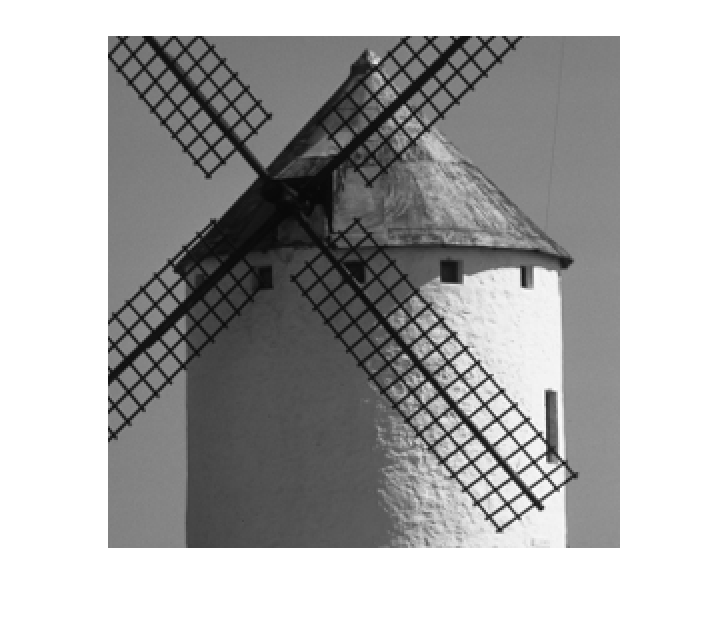

imshow(k);

imshow(k2);

%Medan bilden k visas som en korrekt bild, visas k2 däremot som en helvit bild. Förklara varför.
%SV: Eftersom k2 endast har tal större än 0 så visar imshow alla pixlar som
%vit medan för k så visar den nyanser mellan 0 och 255

**1.4**

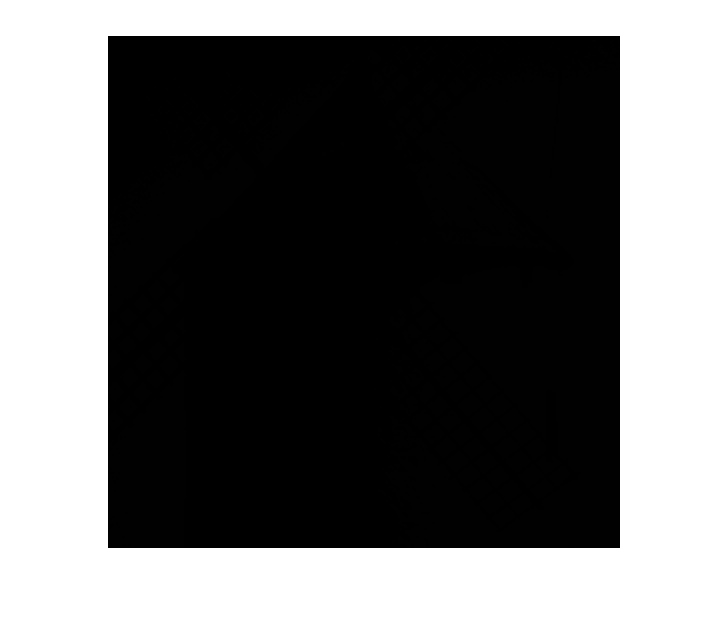

imshow(k/255);

imshow(k2/255);

%Medan den första visas som en helt svart bild, visas den andra som en korrekt bild. Förklara varför. 
%då k/255 så bli samtliga värden under 0 och därav avrundas de till 0 (pga
%uint8) 0 ger svart i skalan. k2 får värden mellan 0 och 1 som återger en
%bild.

## **PART 2**

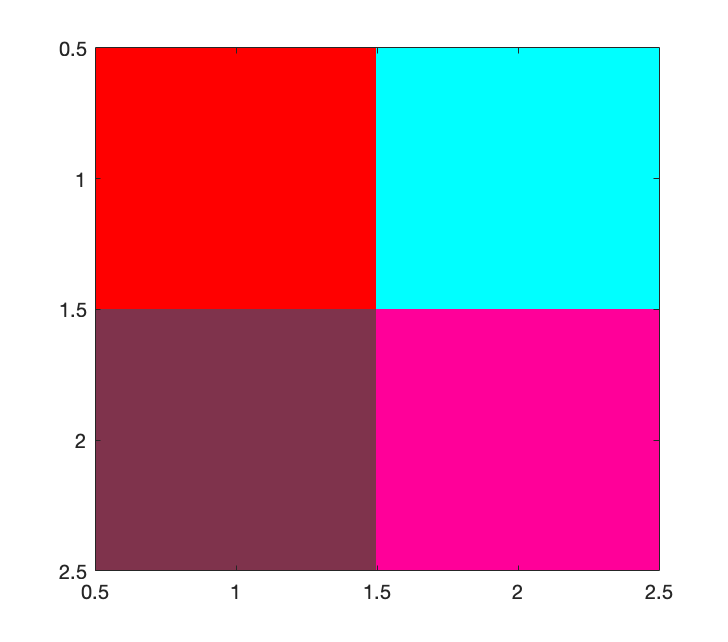

map=([1 0 0; 0 1 1; 0.5 0.2 0.3; 1 0 0.6]);
image([1 , 2 ; 3, 4]);
colormap(map);

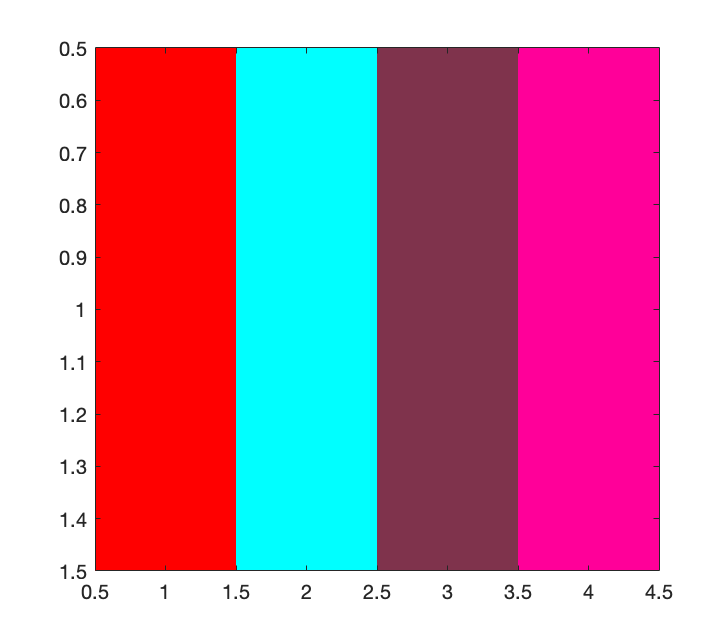


map=([1 0 0; 0 1 1; 0.5 0.2 0.3; 1 0 0.6]);
image([1 , 2 , 3, 4]);
colormap(map);

**2.1**

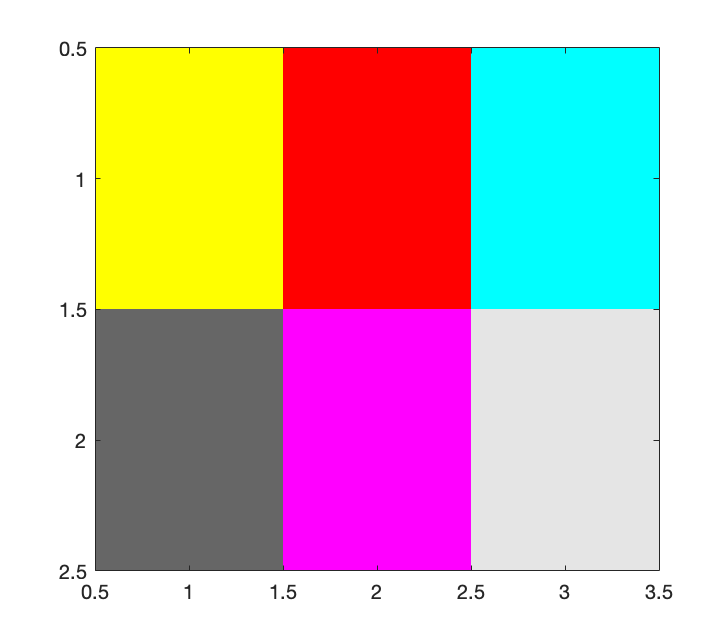

map=([1 1 0; 1 0 0; 0 1 1; 0.4 0.4 0.4; 1 0 1; 0.9 0.9 0.9]);
image([1 , 2 , 3; 4, 5, 6]);
colormap(map);


%Kopiera koden och bilden som svar

%1. Gult (Röd + Grön), upp till vänster
%2. Röd, upp-mitten
%3. Cyan (Grön + Blå), upp till höger
%4. Mörkgrå, ner till vänster
%5. Magenta (Röd + Blå), ner-mitten
%6. Ljusgrå, ner till höger

## **Part 3**

**3.1**

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15]

N =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15



N(1:3:end, 1) %var 3e rad i kolumn 1

ans =      1
    10


N(1:3:end, :) %var 3e rad alla kolumner

ans =      1     2     3
    10    11    12


**3.2**

v1=[1, 1, 1, 1];
v2=[0.5, 0.25, 0, 0.25]; 
v3=[0.25, 0.5, 0, 0.5, 1];
s1=sum(v1 .* v2);
%s2=sum(v1 .* v3);

## Part 4

**4.1**

m6=[1 2 3; 4 5 6; 7 8 9] 

m6 =      1     2     3
     4     5     6
     7     8     9


m7=[-2 3 1; 0 2 -7; 1 3 6]

m7 =     -2     3     1
     0     2    -7
     1     3     6



%logical ger 1 för sant och 0 för falskt

u1= m6>3 %alla element i m6 som är större än 3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)%alla element i m6 som är större än 3 OCH alla i m7 som är lika med -7

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)%alla element i m6 som är större än 3 ELLER alla i m7 som är lika med -7

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)%alla element där m6+m7 är större eller lika med 4 OCH element i m6 större än 5

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


## Part 5

**5.1**

b = imread('Butterfly.tif')

b = 280×420×3 uint8 array
b(:,:,1) =

    38    44    38    45    53    50    50    45    46    42    42    44    42    39    40    45    42    47    50    51    53    58    59    55    57    55    53    53    53    53    51    50    45    52    55    52    50    52    52    51    44    44    46    46    44    44    46    47    43    42    42    40    38    36    35    34    38    37    36    35    35    35    35    35    32    32    33    33    34    35    35    35    34    33    32    33    34    34    32    30    32    31    30    32    34    35    35    33    31    31    33    32    29    33    36    30    29    34    35    31    30    33    34    32    30    31    30    29    29    27    26    26    29    28    27    27    27    26    25    24    24    26    30    28    25    30    35    32    29    30    30    29    28    29    31    33    29    27    27    29    29    27    29    33    30    33    35    33    31    30    32    34    38    34    35    40    41    37    34    34  

b = double(b)/255;

R = (b(:, :, 1)); %Röda kanalen
G = (b(:, :, 2)); %Gröna kanalen
B = (b(:, :, 3)); %Blå kanalen

mygray = (R+G+B)/3

mygray =     0.1817    0.2052    0.1817    0.2092    0.2405    0.2288    0.2288    0.2092    0.2105    0.1948    0.1974    0.2052    0.2000    0.1908    0.1948    0.2157    0.1974    0.2170    0.2327    0.2353    0.2497    0.2680    0.2719    0.2588    0.2654    0.2575    0.2497    0.2497    0.2497    0.2497    0.2418    0.2379    0.2157    0.2431    0.2549    0.2431    0.2353    0.2431    0.2431    0.2392    0.2092    0.2092    0.2170    0.2196    0.2118    0.2131    0.2209    0.2248    0.2105    0.2078
    0.2209    0.2405    0.2131    0.2209    0.2405    0.2248    0.2288    0.2209    0.2065    0.2065    0.2131    0.2131    0.2039    0.1948    0.1987    0.2078    0.2039    0.2248    0.2405    0.2444    0.2497    0.2614    0.2601    0.2510    0.2536    0.2536    0.2497    0.2497    0.2536    0.2497    0.2418    0.2340    0.2588    0.2588    0.2510    0.2392    0.2314    0.2314    0.2235    0.2118    0.2327    0.2327    0.2288    0.2235    0.2118    0.2052    0.2052    0.2013    0.2026

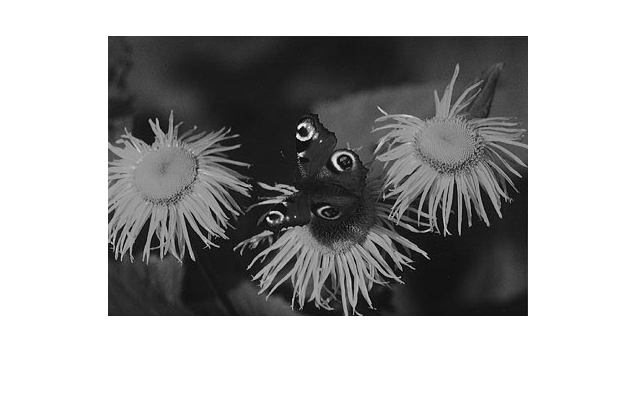


imshow(mygray);

imwrite(mygray, 'mypicture.png');


## Part 6

**6.1**

b61 = mygray(1:2:end, 1:2:end);

Undefined function or variable 'mygray'.

imwrite(b61, 'b61.png');

**6.2 - 6-3**

b62 = samplaner(mygray);
imshow(b62);
imwrite(b62, 'b62.png');

b63_nearest = imresize(b61, 2, 'nearest');
b63_linear = imresize(b61, 2, 'bilinear');
b63_cubic = imresize(b61, 2, 'bicubic');

imshow(b63_nearest);
imshow(b63_linear);
imshow(b63_cubic);

imwrite(b63_nearest, 'b63_nearest.png');
imwrite(b63_linear, 'b63_linear.png');
imwrite(b63_cubic, 'b63_cubic.png');

udda = im2double(imread('kvarn_udda.tif'));

sampel = samplaner(udda);
imshow(sampel);

**6.4**

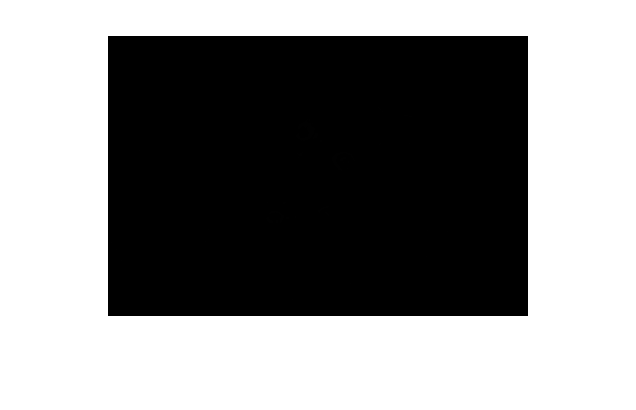

mycolorimage = imread('Butterfly.tif');
mycolorimage = double(mycolorimage)/255;

mycolorimage1 = imread('Butterfly.tif');
imshow(mycolorimage1(:, :, 3)/255)

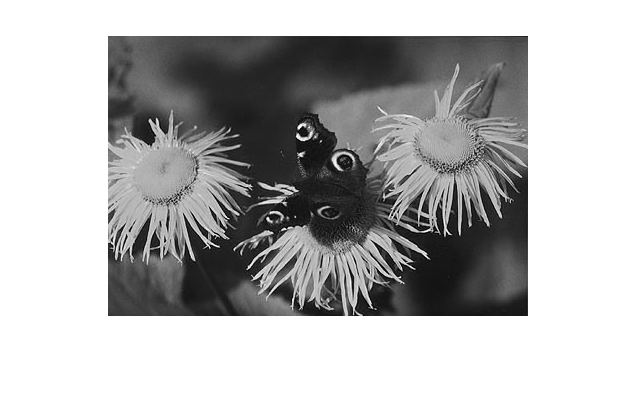

imshow(double(mycolorimage1(:, :, 2))/255)


b64 = imresize(mycolorimage,0.5,'nearest');
b64 = imresize(b64,2,'nearest');

%imshow(mycolorimage);
%imshow(b64);

%imwrite(b64, 'b64.png');

**6.5**

R = (mycolorimage(:, :, 1)); %Röda kanalen
G = (mycolorimage(:, :, 2)); %Gröna kanalen
B = (mycolorimage(:, :, 3)); %Blå kanalen

R2 = imresize(R,0.5,'nearest');
R2 = imresize(R2,2,'nearest');

B2 = imresize(B,0.5,'nearest');
B2 = imresize(B2,2,'nearest');

b65=cat(3, R2, G, B2);

imshow(b65);
imwrite(b65,'b65.png');

**6.6-6.7**

R3 = imresize(R,0.5,'nearest');
R3 = imresize(R3,2,'nearest');

G3 = imresize(G,0.5,'nearest');
G3 = imresize(G3,2,'nearest');

b67=cat(3, R3, G3, B);
imshow(b67);
imwrite(b67, 'b67.png');

**6.8**

bild1 = R+G+B;
bild2 = R-G;
bild3 = R+G-2*B;

bild2 = imresize(bild2,0.5,'nearest');
bild2 = imresize(bild2,2,'nearest');

bild3 = imresize(bild3,0.5,'nearest');
bild3 = imresize(bild3,2,'nearest');

R2 = bild1/3+bild2/2+bild3/6; 
G2 = bild1/3-bild2/2+bild3/6;
B2 = bild1/3-bild3/3;

b68 = cat(3,R2,G2,B2);
imshow(b68);
imwrite(b68, 'b68.png');
